# Parameter Sweep Study - Friction on Motor Shaft

*The rotating shaft of a motor experiences friction, especially if not well lubricated. What effect does this friction have on the motor speed?*

*Understanding the effect of Breakaway and Viscous friction on a rotating shaft*

    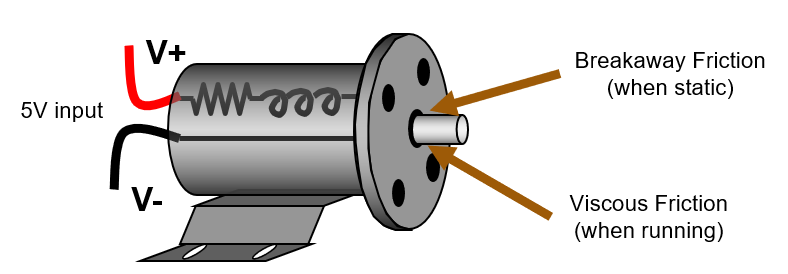

### Description

The friction torque is simulated as a function of relative velocity and is assumed to be the sum of Stribeck, Coulomb, and viscous components, as shown in the following figure.

    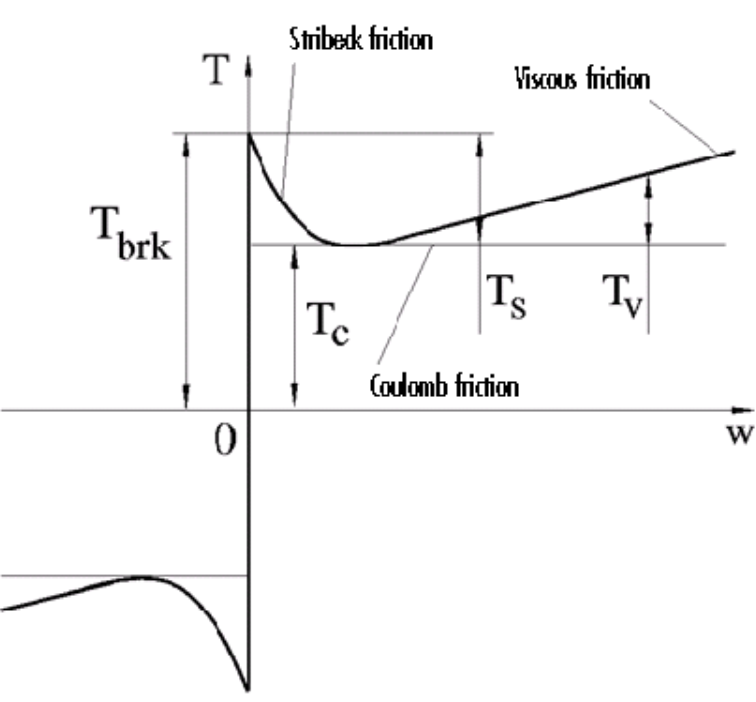

In this example, we vary the values of both the breakaway friction torque `Tbrk` and viscous friction torque `Tv`, and review the effect on the motor speed when supplied with a constant 5V input.

## Setting up model

Ensure the model can be opened, compiled and simulated without errors.

mdl = 'ssc_dcmtr_sl';
open_system(mdl)
sim(mdl);

## Define inputs and variables to be varied

t = (0:0.01:10)';
input_ds = Simulink.SimulationData.Dataset;   
input_ds = input_ds.setElement(1, timeseries(ones(size(t)),t));

input_Tbreakaway = (0.001 : 0.002: 0.01)';
input_Tviscous = (0.000 : 0.005: 0.02)';

numSims = length(input_Tbreakaway)*length(input_Tviscous)

numSims = 25

Create a [Simulink.SimulationInput](https://www.mathworks.com/help/simulink/slref/simulink.simulationinput-class.html) object and set the external inputs and add variables used by the model into the Simulink.SimulationInput object.

runID = 1;
for v1 = 1:length(input_Tbreakaway)
    for v2 = 1:length(input_Tviscous)     

        in(runID) = Simulink.SimulationInput(mdl);
        % in(runID) = setExternalInput(in(RunID),input_ds)
        in(runID) = in(runID).setVariable('Tbrk',input_Tbreakaway(v1),'Workspace',mdl);
        in(runID) = in(runID).setVariable('Tvis',input_Tviscous(v2),'Workspace',mdl); 
        disp(['runID = ' num2str(runID) ';  Tbrk = ' num2str(input_Tbreakaway(v1)) ';  Tvis = ' num2str(input_Tviscous(v2)) ])
        
        runID = runID+1;
    end
end

runID = 1;  Tbrk = 0.001;  Tvis = 0
runID = 2;  Tbrk = 0.001;  Tvis = 0.005
runID = 3;  Tbrk = 0.001;  Tvis = 0.01
runID = 4;  Tbrk = 0.001;  Tvis = 0.015
runID = 5;  Tbrk = 0.001;  Tvis = 0.02
runID = 6;  Tbrk = 0.003;  Tvis = 0
runID = 7;  Tbrk = 0.003;  Tvis = 0.005
runID = 8;  Tbrk = 0.003;  Tvis = 0.01
runID = 9;  Tbrk = 0.003;  Tvis = 0.015
runID = 10;  Tbrk = 0.003;  Tvis = 0.02
runID = 11;  Tbrk = 0.005;  Tvis = 0
runID = 12;  Tbrk = 0.005;  Tvis = 0.005
runID = 13;  Tbrk = 0.005;  Tvis = 0.01
runID = 14;  Tbrk = 0.005;  Tvis = 0.015
runID = 15;  Tbrk = 0.005;  Tvis = 0.02
runID = 16;  Tbrk = 0.007;  Tvis = 0
runID = 17;  Tbrk = 0.007;  Tvis = 0.005
runID = 18;  Tbrk = 0.007;  Tvis = 0.01
runID = 19;  Tbrk = 0.007;  Tvis = 0.015
runID = 20;  Tbrk = 0.007;  Tvis = 0.02
runID = 21;  Tbrk = 0.009;  Tvis = 0
runID = 22;  Tbrk = 0.009;  Tvis = 0.005
runID = 23;  Tbrk = 0.009;  Tvis = 0.01
runID = 24;  Tbrk = 0.009;  Tvis = 0.015
runID = 25;  Tbrk = 0.009;  Tvis = 0.02


clear t v1 v2 runID

## Simulate the model

In series

outseries = sim(in, 'ShowSimulationManager', 'on');

In parallel

outparallel = parsim(in,'ShowSimulationManager', 'off');

## Working with the results in Simulink.SimulationOutput class

Plot one of the results

plot(outseries)

Analyze results with the help of plots

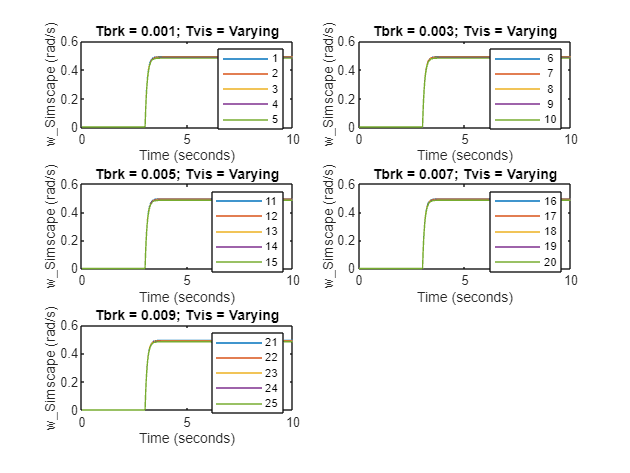

figure; % Effect of constant Tbrk on Varying Tvis
for i = 0:4
    subplot(3,2,i+1)

        runs = ((5*i)+1) : 1: ((5*i)+5);

        for j = 1:length(runs)
            plot(outseries(1,runs(j)).logsout{2}.Values)
            hold on
        end
       hold off

       legend(cellstr(num2str(runs')))
       title (['Tbrk = ' num2str(input_Tbreakaway(i+1)) '; Tvis = Varying'])
end

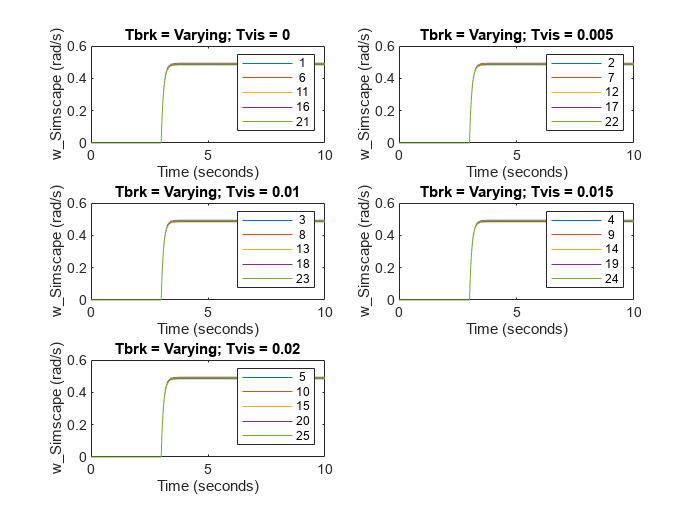

figure; % Effect of constant Tbrk on Varying Tvis
for i = 0:4
    subplot(3,2,i+1)

        runs = (i+1) : 5: numSims;

        for j = 1:length(runs)
            plot(outseries(1,j).logsout{2}.Values)
            hold on
        end
       hold off

       legend(cellstr(num2str(runs')))
       title (['Tbrk = Varying; Tvis = ' num2str(input_Tviscous(i+1)) ])
end

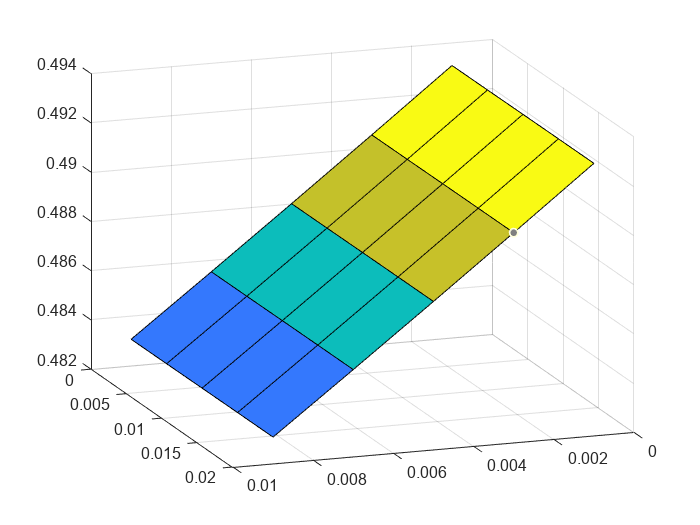

figure % Surface plot of Tbrk, Tvis, and final Motor speed

    % Create a meshgrid of input values
        [X,Y] = meshgrid(input_Tbreakaway, input_Tviscous);
        Z = X + Y;
    % Update Z with values from simulations
        runID = 1;
        for i = 1:5
            for j = 1:5
                Z(i,j) = max(outseries(1, runID).logsout{2}.Values);
                runID = runID+1;
            end
        end
    % Plot the surface plot
        surf(X,Y,Z)

clear i j runs X Y Z runID

### **Inferences from the data**

The results show 

- The settling motor speed `motorspeed` is affected by both `Tbrk` and `Tvis`

- `Tvis` is independent of `Tbrk`  

## Additional: Comparing Series vs Parllel Simulation speeds

Look at timing information

figure;
totaltime = zeros(1,numSims);
for i = 1:numSims
    totaltime(i) = outseries(i).SimulationMetadata.TimingInfo.TotalElapsedWallTime;
end
disp(['Average Simulation Time = ', num2str(mean(totaltime))])

Average Simulation Time = 1.272


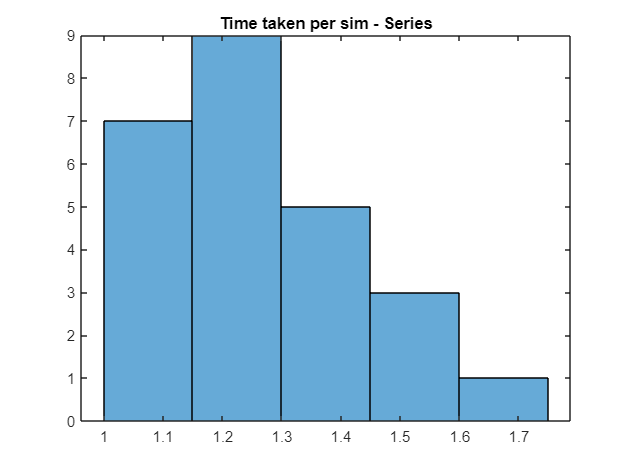

histogram(totaltime,5)
title('Time taken per sim - Series')

figure;
totaltime = zeros(1,numSims);
for i = 1:numSims
    totaltime(i) = outparallel(i).SimulationMetadata.TimingInfo.TotalElapsedWallTime;
end
disp(['Average Simulation Time = ', num2str(mean(totaltime))])

Average Simulation Time = 3.8557


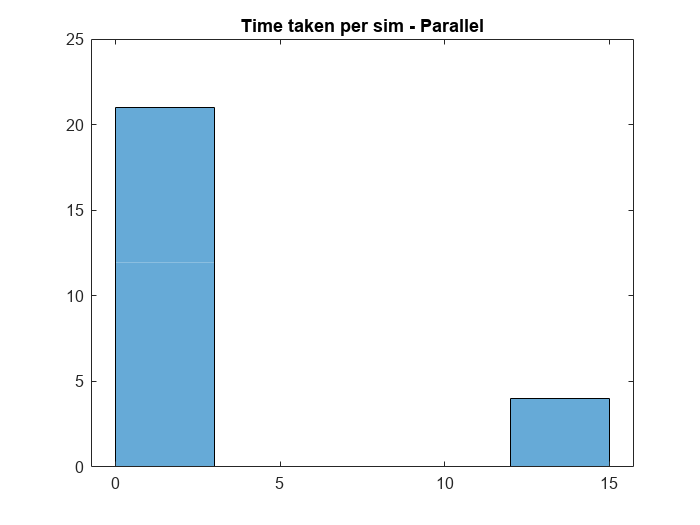

histogram(totaltime,5)
title('Time taken per sim - Parallel')

clear i totaltime